%画出Ryy
ny = 7000;
Ryy_y2 = conv(y2, flipud(y2))

Ryy_y2 = 1.0e+04 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


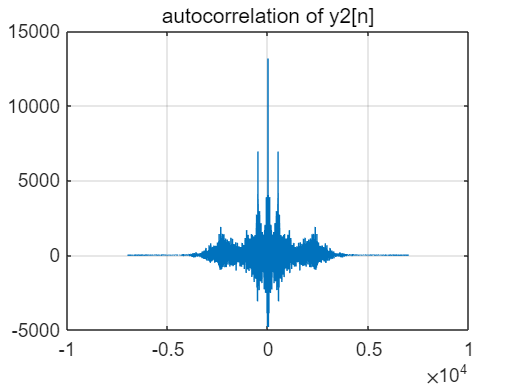

figure(1);
plot(-ny+1 : ny - 1, Ryy_y2);
grid on;
title('autocorrelation of y2[n]')

%通过Ryy得到N = 500
N = 500;
Ryy = conv(z, flipud(z));
mini_norm = 100000;
best_alpha = 0;

%遍历找best_alpha
for i = 1 : 9
    tic;
    alpha = 0.1 * i
    x_temp = filter(1, [1, zeros(1, N-1), alpha], y2);
    Rxx_temp = conv(x_temp, flipud(x_temp)).';
    Ryy_temp = (1 + alpha^2) * Rxx_temp + alpha * [zeros(1, N), Rxx_temp(1 : 2 * ny - 1 - N)] + alpha * [Rxx_temp(N+1 : 2*ny-1), zeros(1, N)];
    error = Ryy_y2 - Ryy_temp;
    if norm(error, 2) < mini_norm
        mini_norm = norm(error, 2);
        best_alpha = alpha;
    end
    toc;
end

alpha = 0.1000

a_y2 = [1, zeros(1, N - 1), best_alpha];
x2 = filter(1, a_y2, y2); %去噪y2
sound(x2)
Rxx_x2 = conv(x2, flipud(x2));

figure(2);
subplot(2, 1, 1);
plot(-ny+1 : ny-1, Rxx_x2);
grid on;
title('autocorrelation of y2[n] without echo')

subplot(2, 1, 2);
plot(ny, x2);
grid on;
title('y2[n] without echo')

